Experiments with multiplicative and common noise

% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\Simulations'

Reduce t_max from 1e4 to 1e3 for computational speed.

% Default Parameters
dt = 0.02; 
tmax = 1000;
t = 0:dt:tmax;   
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

Benchmark model from Garnier Papanicolaou

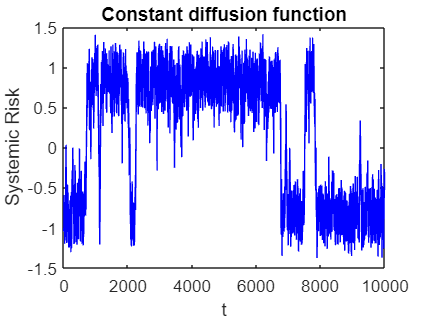

% Define SDE
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig;    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'yes');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant diffusion function")

Carmona noise $\mathrm{~d}\widetilde{W}_{t}^{i}=\rho \mathrm{~d} W_{t}^{0}+\sqrt{1-\rho^{2}} \mathrm{~d} W_{t}^{i}$

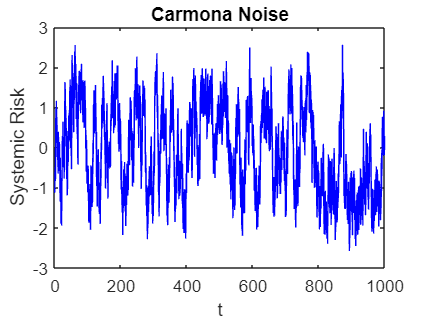

% Carmona Common Noise
g = @(t, x) sig.*CarmonaNoise(N, 0.5); 

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Carmona Noise")

Giesecke noise $\mathrm{~d}\widetilde{W}_{t}^{i}=\rho X_{t}^{i} \mathrm{~d}W_{t}^{0}+ q \sqrt{X_{t}^{i}}  \mathrm{~d} W_{t}^{i}$ 

% Multiplicative and Common Noise (Like in Giesecke)
g = @(t, x) sig.*MultiNoise(N, x, 0.5, sqrt(0.5));     

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');

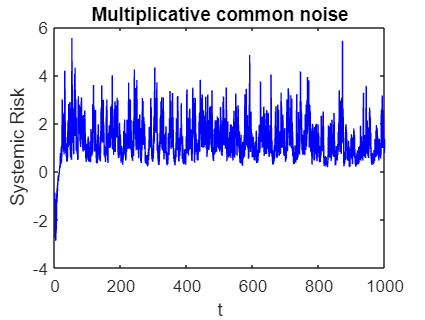

xlabel('t'); ylabel('Systemic Risk');
title("Multiplicative common noise")

Without bistable potential